# Electricity Statistics

Load price and usage data, and compute revenue.

load electricity
revenue = price.*usage

revenue = 1.0e+12 *

    0.6841    0.6952    0.7041    0.7254    0.8034    0.7581    0.8421    0.8351    0.8073    0.8427    0.8392    0.9827    0.9429    0.9946    1.0473    1.0672    1.1496    1.2599    1.3524    1.4954    1.5475    1.5771    1.4360    1.5100    1.7075    1.6638
    0.5572    0.6042    0.6389    0.6502    0.7037    0.6942    0.7502    0.7202    0.6902    0.6868    0.7600    0.8030    0.7907    0.8897    0.9363    0.9341    1.0243    1.2016    1.2045    1.2885    1.3374    1.3284    1.2424    1.3153    1.5338    1.5209
    0.5443    0.5751    0.5905    0.6478    0.6456    0.6468    0.7034    0.6709    0.6885    0.7066    0.6854    0.7721    0.7785    0.8312    0.8525    0.9235    1.0358    1.0854    1.1198    1.2014    1.2414    1.2090    1.1621    1.3016    1.3996    1.4427
    0.5015    0.5256    0.5497    0.5665    0.5766    0.5769    0.6148    0.6095    0.6103    0.6250    0.6219    0.6974    0.7151    0.7357    0.7628    0.8002    0.9220    0.9595    1.0075    1.

Calculate revenue in 2015 dollars.

revenue2015 = revenue.*dollar2015;

#### Plot annual min, max, and average usage

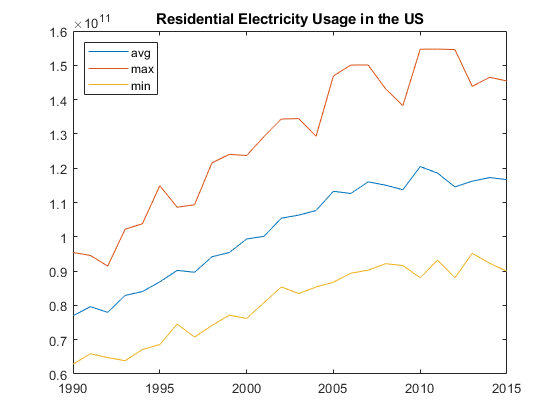

annual = mean(usage);
plot(yr,annual)
hold on
plot(yr,max(usage))
plot(yr,min(usage))
hold off
legend("avg","max","min","Location","northwest")
title("Residential Electricity Usage in the US")

#### Plot average usage by month

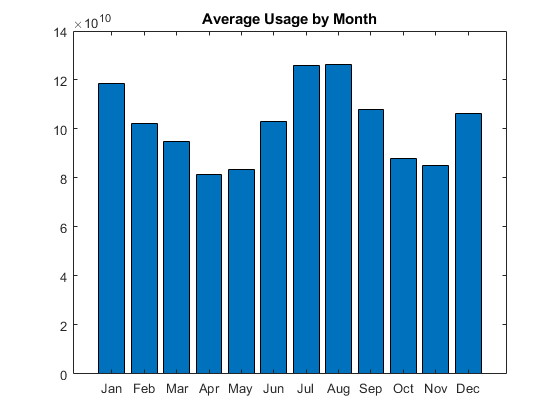

monthly = mean(usage,2);
bar(mth,monthly)
title("Average Usage by Month")
xticks(1:12)
mthNames = month(datetime(2000,1:12,1),'shortname');
xticklabels(mthNames)

#### Plot median year-over-year growth in revenue

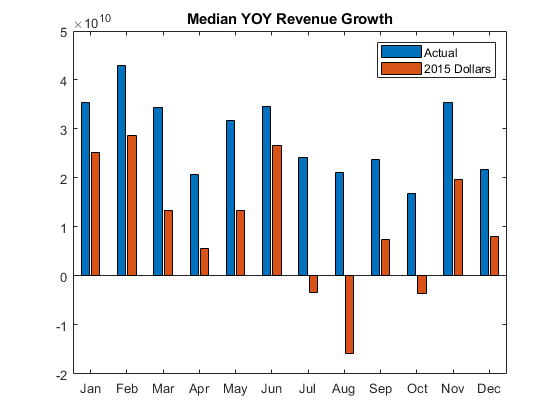

YoY = diff(revenue,[],2);
medYoY = median(YoY,2);
YoY2015 = diff(revenue2015,[],2);
medYoY2015 = median(YoY2015,2);
bar(mth,[medYoY medYoY2015])
xticks(1:12)
xticklabels(mthNames)
legend("Actual","2015 Dollars")
title("Median YOY Revenue Growth")